We get a cardinal function if we use data that is one at a node and zero at the others. 

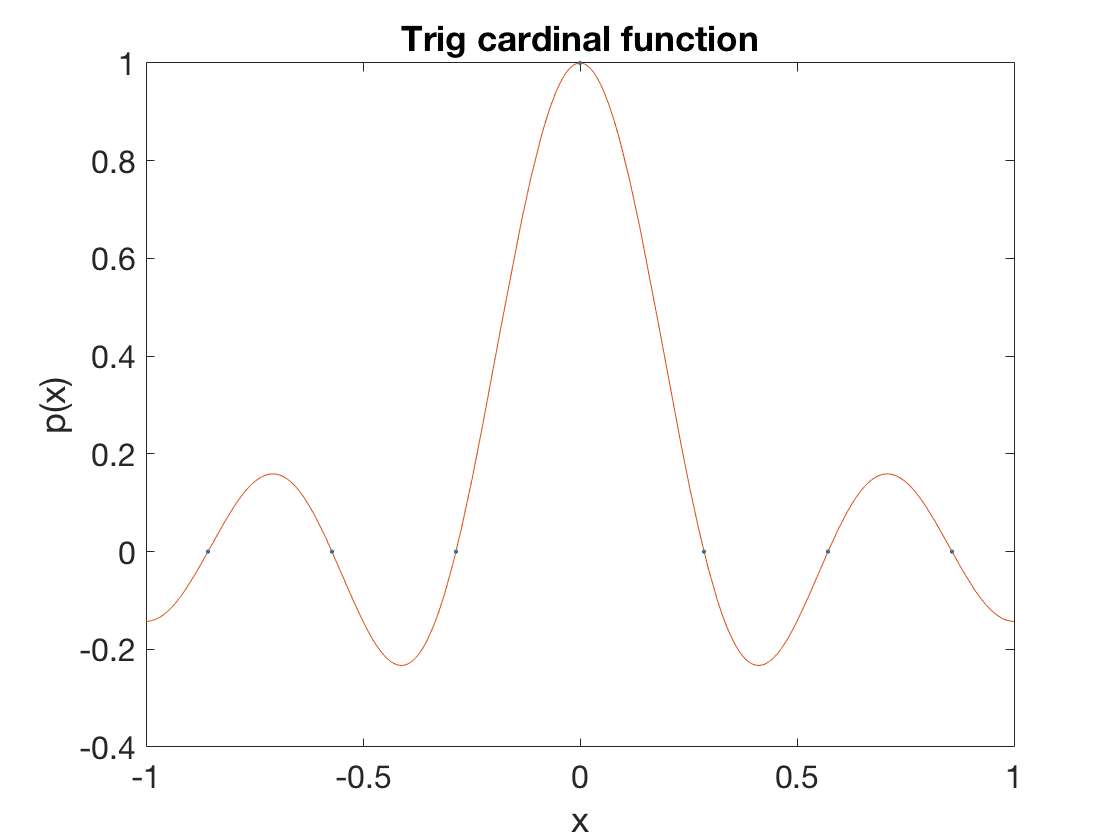

N = 7;  n = (N-1)/2;
t = 2*(-n:n)'/N;
y = zeros(N,1);  y(n+1) = 1;
plot(t,y,'.'), hold on

p = triginterp(t,y);
fplot(p,[-1 1])
xlabel('x'), ylabel('p(x)')   % ignore this line
title('Trig cardinal function')    % ignore this line

Here is a 2-periodic function and one of its interpolants.

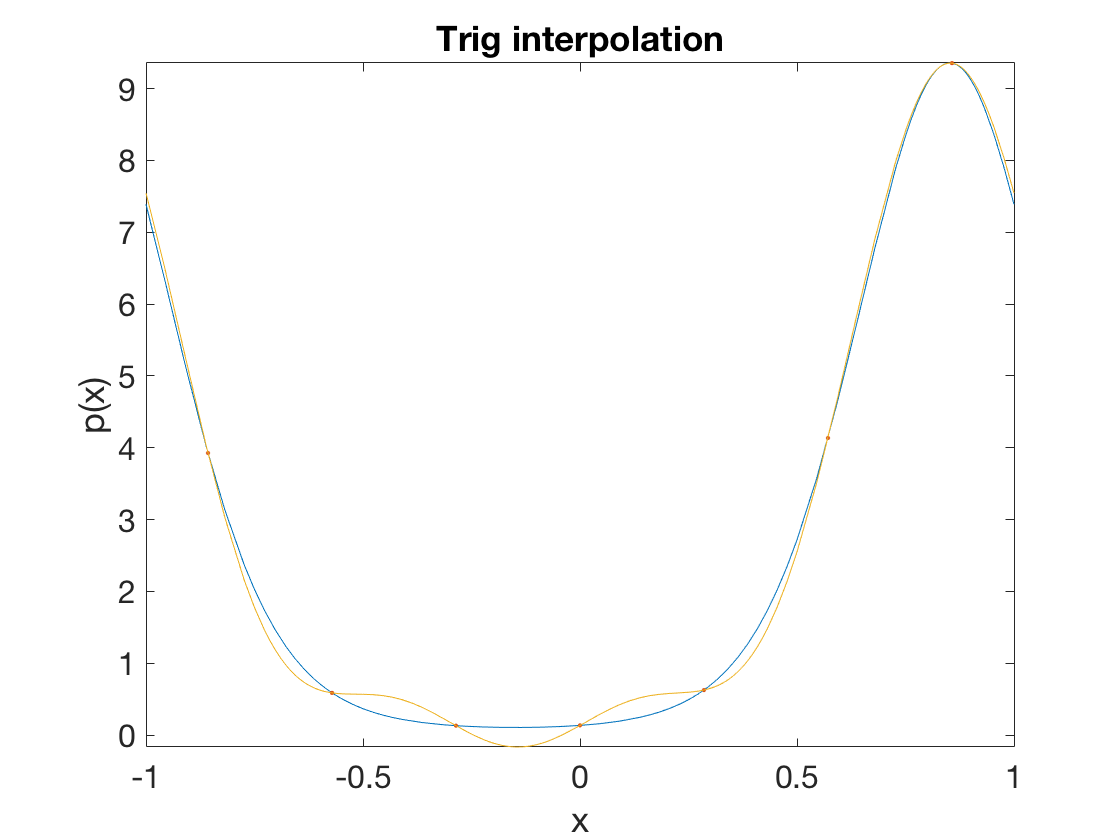

clf
f = @(x) exp(sin(pi*x)-2*cos(pi*x));
fplot(f,[-1 1]), hold on
y = f(t);  plot(t,y,'.')
fplot(triginterp(t,y),[-1 1])
xlabel('x'), ylabel('p(x)')   % ignore this line
title('Trig interpolation')    % ignore this line

The convergence of the interpolant is exponential (spectral). We let $N$ go needlessly large here in order to demonstrate that unlike polynomials, trigonometric interpolation is stable on equally spaced nodes.

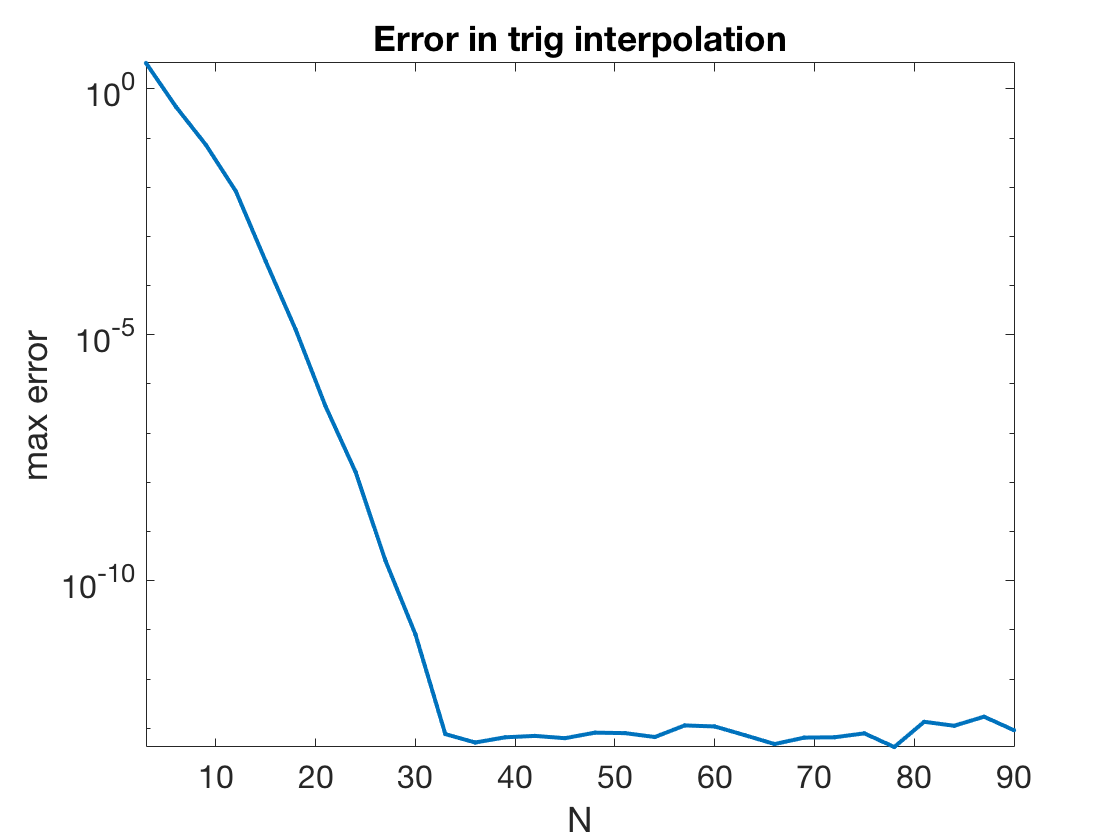

N = (3:3:90)';
err = 0*N;
x = linspace(-1,1,1601)';  % for measuring error
for k = 1:length(N)
    n = (N(k)-1)/2;   t = 2*(-n:n)'/N(k);
    p = triginterp(t,f(t));
    err(k) = norm(f(x)-p(x),inf);
end
clf, semilogy(N,err,'.-')
axis tight, title('Error in trig interpolation')   % ignore this line
xlabel('N'), ylabel('max error')   % ignore this line